# Color-Based Segmentation Using K-Means Clustering

This example shows how to segment colors in an automated fashion using the L*a*b* color space and K-means clustering.

## Step 1: Read Image

Read in `hestain.png`, which is an image of tissue stained with hemotoxylin and eosin (H&E). This staining method helps pathologists distinguish different tissue types.

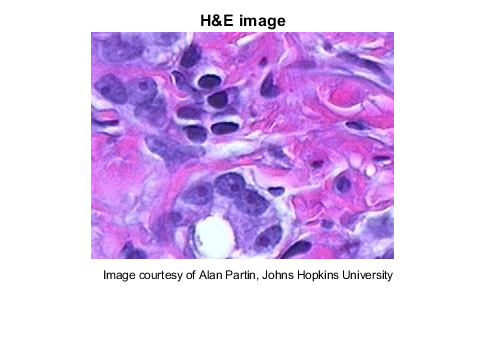

he = imread('hestain.png');
imshow(he), title('H&E image');
text(size(he,2),size(he,1)+15,...
     'Image courtesy of Alan Partin, Johns Hopkins University', ...
     'FontSize',7,'HorizontalAlignment','right');

## Step 2: Convert Image from RGB Color Space to L*a*b* Color Space

How many colors do you see in the image if you ignore variations in brightness? There are three colors: white, blue, and pink. Notice how easily you can visually distinguish these colors from one another. The L*a*b* color space (also known as CIELAB or CIE L*a*b*) enables you to quantify these visual differences.

The L*a*b* color space is derived from the CIE XYZ tristimulus values. The L*a*b* space consists of a luminosity layer 'L*', chromaticity-layer 'a*' indicating where color falls along the red-green axis, and chromaticity-layer 'b*' indicating where the color falls along the blue-yellow axis. All of the color information is in the 'a*' and 'b*' layers. You can measure the difference between two colors using the Euclidean distance metric.

Convert the image to L*a*b* color space using `rgb2lab`.

lab_he = rgb2lab(he);

## Step 3: Classify the Colors in 'a*b*' Space Using K-Means Clustering

Clustering is a way to separate groups of objects. K-means clustering treats each object as having a location in space. It finds partitions such that objects within each cluster are as close to each other as possible, and as far from objects in other clusters as possible. K-means clustering requires that you specify the number of clusters to be partitioned and a distance metric to quantify how close two objects are to each other.

Since the color information exists in the 'a*b*' color space, your objects are pixels with 'a*' and 'b*' values. Convert the data to data type `single` for use with `imsegkmeans`. Use `imsegkmeans` to cluster the objects into three clusters.

ab = lab_he(:,:,2:3);
ab = im2single(ab);
nColors = 3;
% repeat the clustering 3 times to avoid local minima
pixel_labels = imsegkmeans(ab,nColors,'NumAttempts',3);

For every object in your input, `imsegkmeans` returns an index, or a label, corresponding to a cluster. Label every pixel in the image with its pixel label.

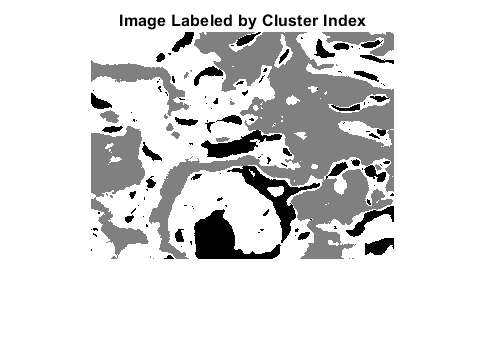

imshow(pixel_labels,[])
title('Image Labeled by Cluster Index');

## Step 4: Create Images that Segment the H&E Image by Color

Using `pixel_labels`, you can separate objects in `hestain.png` by color, which will result in three images.

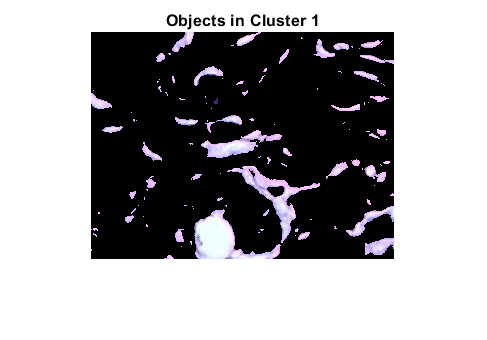

mask1 = pixel_labels==1;
cluster1 = he .* uint8(mask1);
imshow(cluster1)
title('Objects in Cluster 1');

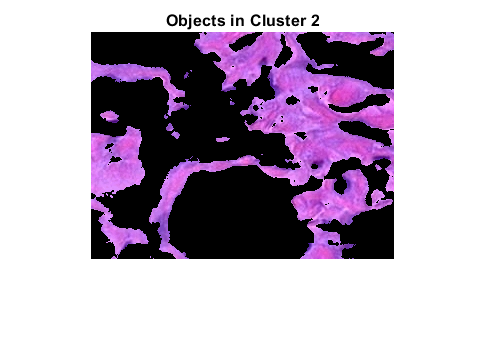

mask2 = pixel_labels==2;
cluster2 = he .* uint8(mask2);
imshow(cluster2)
title('Objects in Cluster 2');

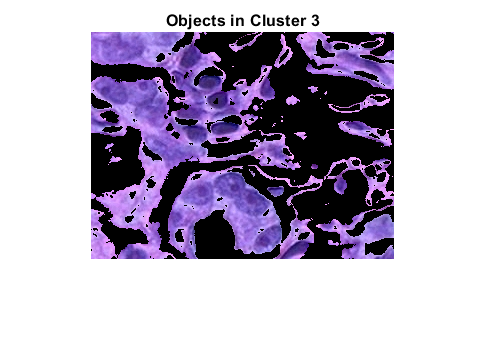

mask3 = pixel_labels==3;
cluster3 = he .* uint8(mask3);
imshow(cluster3)
title('Objects in Cluster 3');

## Step 5: Segment the Nuclei

Cluster 3 contains the blue objects. Notice that there are dark and light blue objects. You can separate dark blue from light blue using the 'L*' layer in the L*a*b* color space. The cell nuclei are dark blue.

Recall that the 'L*' layer contains the brightness values of each color. Extract the brightness values of the pixels in this cluster and threshold them with a global threshold using `imbinarize`. The mask `is_light_blue` gives the indices of light blue pixels. 

L = lab_he(:,:,1);
L_blue = L .* double(mask3);
L_blue = rescale(L_blue);
idx_light_blue = imbinarize(nonzeros(L_blue));

Copy the mask of blue objects, `mask3`, then remove the light blue pixels from the mask. Apply the new mask to the original image and display the result. Only dark blue cell nuclei are visible.

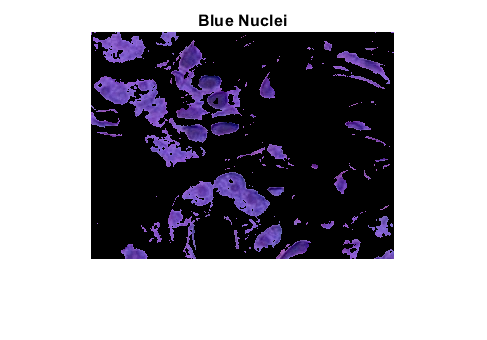

blue_idx = find(mask3);
mask_dark_blue = mask3;
mask_dark_blue(blue_idx(idx_light_blue)) = 0;

blue_nuclei = he .* uint8(mask_dark_blue);
imshow(blue_nuclei)
title('Blue Nuclei');

*Copyright 1993-2018 The MathWorks, Inc.*